# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.3 三维绘图

#### 2.3.4 曲面裁剪

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

利用 Matlab 不显示 NaN 的特性；

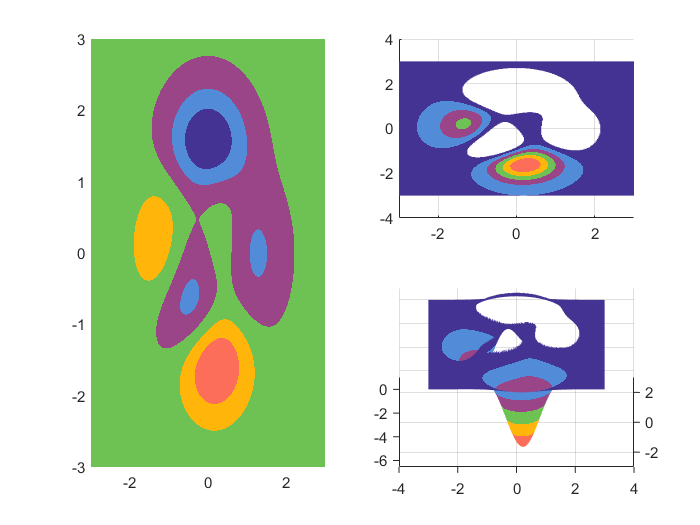

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors();            
% 生成多峰图
figure;
n = 300;
[x, y, z] = peaks(n);
% 绘制原图
subplot(2, 2, [1,3])
surf(x, y, z);
xlim([-3, 3]);
ylim([-3, 3]);
shading interp
view(0, 90)
% 裁剪
z(z > 1) = NaN;
subplot(2, 2, 2)
surf(x, y, z);
xlim([-3, 3]);
shading interp
view(0, 90)
subplot(2, 2, 4)
surf(x, y, z);
colormap(all_themes{1});
shading interp
view(0, 45)